clear all; close all; clc;

**Load all the data 60 HABD**

filename = 'ex_trsp_habd60.xcs';
data = load(filename);

PS = PLOT_STANDARDS(); % Assuming PLOT_STANDARDS defines your color scheme.

time = data(:, 1);
joint_angles = data(:,2:end);
J1 = data(:,2);
J2 = data(:,3);
J3 = data(:,4);
J4 = data(:,5);

J5 = data(:,6);
J6 = data(:,7);
J7 = data(:,8);

**Define Start and End of the whole trajectory**

- J6 is the 1st one to move in the horizontal abduction hence its 1st change is the one of the initial time

indexStart_Go = 1;
while (J6(indexStart_Go) == J6(indexStart_Go+1))
    indexStart_Go = indexStart_Go+1;
end
initialTime_Go = time(indexStart_Go) %sec

initialTime_Go = 0.3792

% Find indices corresponding to endTime_Return
indexEnd_Return = 560;
endTime_Return = time(indexEnd_Return) % time of the trajectory's end

endTime_Return = 11.2069

% Select the time and joint angles within the interval
interval_time = time(indexStart_Go:indexEnd_Return);
interval_angles = joint_angles(indexStart_Go:indexEnd_Return, :);

% Shift the time axis by initialTime_Go
shifted_time = interval_time - initialTime_Go;
trajectoryDuration = shifted_time(end) %sec

trajectoryDuration = 10.8277

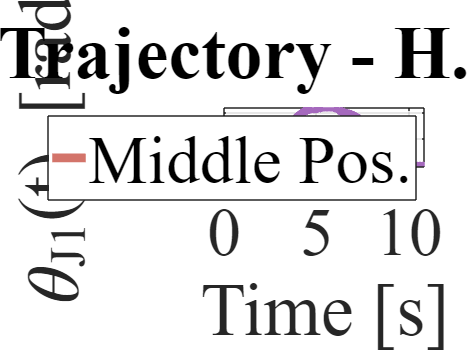

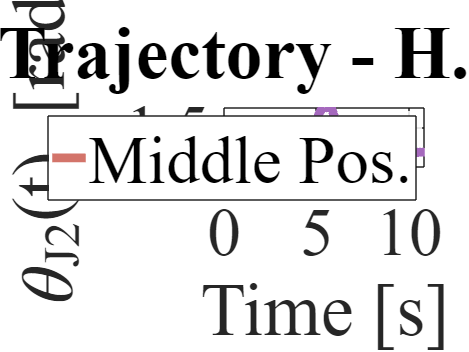

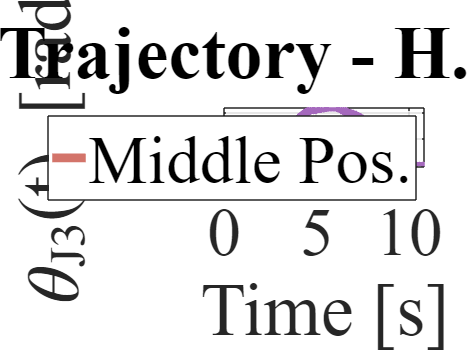

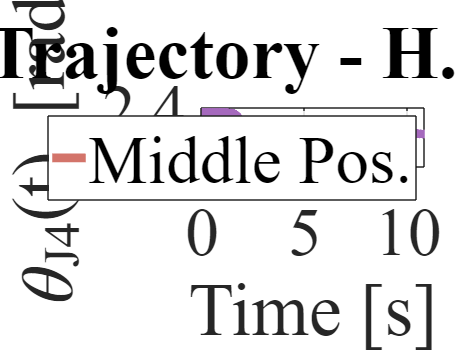

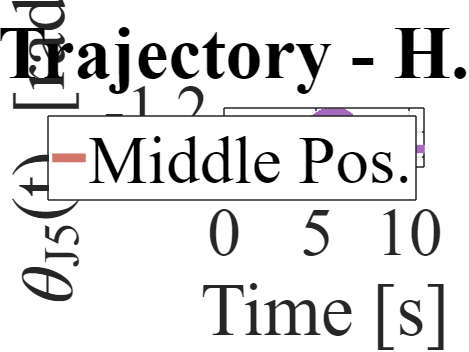

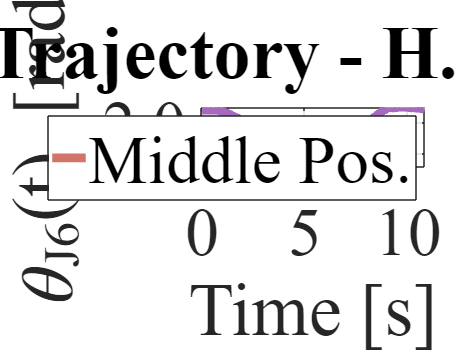

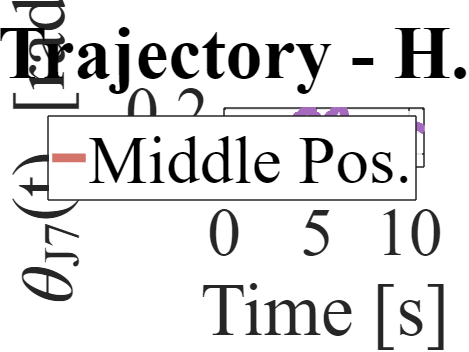

% Font settings
font_name = 'Times'; % Font name
font_size = 60; % Font size

% Definisco i titoli specifici per ogni joint
titles = {...
    'J1 Trajectory - H. Abd 60°', ...
    'J2 Trajectory - H. Abd 60°', ...
    'J3 Trajectory - H. Abd 60°', ...
    'J4 Trajectory - H. Abd 60°', ...
    'J5 Trajectory - H. Abd 60°', ...
    'J6 Trajectory - H. Abd 60°', ...
    'J7 Trajectory - H. Abd 60°'};

% Dimensioni desiderate della figura (larghezza maggiore rispetto all'altezza)
width = 90;  % in centimeters
height = 20;  % in centimeters

% Positione della linea tratto-punto (metà del tempo)
line_position = (shifted_time(1) + shifted_time(end)) / 2;

% Plot ogni joint individualmente in una nuova finestra
num_joints = size(interval_angles, 2);

for i = 1:num_joints
    figure;

     % Imposta la dimensione di esportazione per fare in modo che il salvataggio
    % avvenga con la dimensione desiderata
    set(gcf, 'PaperUnits', 'centimeters');
    set(gcf, 'PaperPosition', [0, 0, width, height]);

    % Crea il plot
    plot(shifted_time, interval_angles(:, i), 'LineWidth', 8, 'Color', PS.DBlue1);
    
    % Aggiungi la linea tratto-punto in corrispondenza del tempo centrale
    h_line = xline(line_position, '--', 'LineWidth', 8, 'Color', PS.DRed2);

    % Imposta titolo e assi
    title(titles{i}, 'FontName', font_name, 'FontSize', font_size);
    xlabel('Time [s]', 'FontName', font_name, 'FontSize', font_size);
    ylabel(['\theta_{J', num2str(i), '}(t) [rad]'], 'FontName', font_name, 'FontSize', font_size); % Specific ylabel for each joint
    xlim([0 max(shifted_time)]);

    % Set the font properties for axes
    ax = gca; % Get current axis
    ax.FontName = font_name; % Set font name
    ax.FontSize = font_size; % Set font size

    % Imposta i tick sugli assi con una sola cifra decimale
    ax.YTickLabel = num2str(get(gca, 'YTick')', '%.1f'); % Set Y axis ticks with 1 decimal place
    
    grid on;
    
    % Aggiungi la legenda per la linea tratto-punto
    legend(h_line, 'Middle Pos.', 'FontName', font_name, 'FontSize', font_size, 'Location', 'northeast');

    % Salva il grafico come file SVG con dimensioni specifiche
    filename = ['J', num2str(i), '_original60.svg'];
    print(gcf, filename, '-dsvg');
end

**Go trajectory**

% Find the time index where J1 reaches its maximum (end of the go movement)
[~, indexMax_J1] = max(interval_angles(:, 1))

indexMax_J1 = 265

timeMax_J1 = shifted_time(indexMax_J1)

timeMax_J1 = 5.2840

go_time = shifted_time(1:indexMax_J1);
go_angles = interval_angles(1:indexMax_J1, :);

- **Initial position of each Joint (only Go)**

initial_positions = interval_angles(1,:) %rad

initial_positions =    -0.0760   -1.5280   -0.0760    2.3640   -1.4390    2.4080   -0.3410


startPosJ1 = initial_positions(1);
startPosJ2 = initial_positions(2);
startPosJ3 = initial_positions(3);
startPosJ4 = initial_positions(4);
startPosJ5 = initial_positions(5);
startPosJ6 = initial_positions(6);
startPosJ7 = initial_positions(7);

- **Final position of each Joint (only Go)**

final_positions = interval_angles(indexMax_J1,:) %rad

final_positions =     0.2380   -1.4760    0.2320    2.0090   -1.2260    0.5850   -0.2780


endPosJ1 = final_positions(1);
endPosJ2 = final_positions(2);
endPosJ3 = final_positions(3);
endPosJ4 = final_positions(4);
endPosJ5 = final_positions(5);
endPosJ6 = final_positions(6);
endPosJ7 = final_positions(7);

maxPosJ6 = startPosJ6 %rad

maxPosJ6 = 2.4080

minPosJ6 = interval_angles(indexMax_J1,6) %rad

minPosJ6 = 0.5850

**Linear Interpolation J6**

% Find the indices for time interval 
start_time = 0;
end_time = 5;

start_index = find(go_time >= start_time, 1, 'first')

start_index = 1

end_index = find(go_time <= end_time, 1, 'last')

end_index = 250

% Interpolation data
x = go_time(start_index:end_index); % take the time interval within the shifted one (only the go trajectory)
y = go_angles(start_index:end_index, 6); % J6 angles

% Coeff of interpolation line
p6 = polyfit(x, y, 1); % Linear fit

**Go trajectories in function of J6**

% 5th Polynomial fit for each joint wrt J6
go_fit_results = cell(num_joints, 1);
go_fitted_angles(:,6) = polyval(p6, go_time);

maxPosJ6_fitted = go_fitted_angles(1,6)

maxPosJ6_fitted = 2.7499

minPosJ6_fitted = go_fitted_angles(end,6)

minPosJ6_fitted = 0.4804

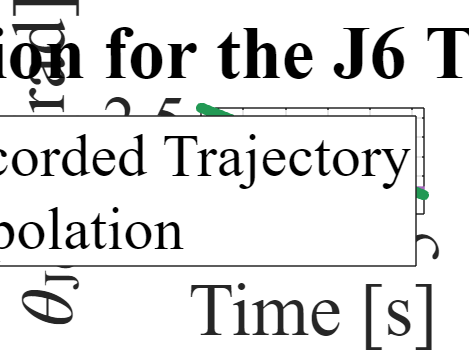

for i = 1:num_joints
    if i == 6
        go_fit_results{i} = p6;
    else
        p = polyfit(go_fitted_angles(:,6), go_angles(:, i), 5);
        go_fit_results{i} = p;
        go_fitted_angles(:, i) = polyval(p, go_fitted_angles(:,6));
    end
end

% Plot interpolating line for J6
figure;

% Imposta la dimensione di esportazione per fare in modo che il salvataggio
% avvenga con la dimensione desiderata

% Dimensioni desiderate della figura (larghezza maggiore rispetto all'altezza)
width = 90;  % in centimeters
height = 30;  % in centimeters

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0, 0, width, height]);

plot(go_time, go_angles(:, 6), '-', 'DisplayName', 'Original Recorded Trajectory', 'Color', PS.DBlue1, 'LineWidth', 8);
grid on;
hold on;

plot(go_time, go_fitted_angles(:,6), 'DisplayName', 'Linear Interpolation', 'LineWidth', 8, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 27, 'MarkerEdgeColor', PS.Green3, 'MarkerFaceColor', PS.Green3);
xlim([0 max(go_time)]);
xlabel('Time [s]', 'FontName', font_name, 'FontSize', font_size);
ylabel('\theta_{J6}(t) [rad]', 'FontName', font_name, 'FontSize', font_size);

xticks(0:1:max(go_time));
yticks(minPosJ6_fitted:0.5:maxPosJ6_fitted);
title('Linear Interpolation for the J6 Trajectory - H. Abd. 60°', 'FontName', font_name, 'FontSize', font_size);
legend;

% Set the font properties for axes
ax = gca; % Get current axis
ax.FontName = font_name; % Set font name
ax.FontSize = font_size; % Set font size
% Imposta i tick sugli assi con una sola cifra decimale
    ax.YTickLabel = num2str(get(gca, 'YTick')', '%.1f'); % Set Y axis ticks with 1 decimal place

% Salva il grafico come file SVG con dimensioni specifiche
filename = ['J6_interp60.svg'];
print(gcf, filename, '-dsvg');

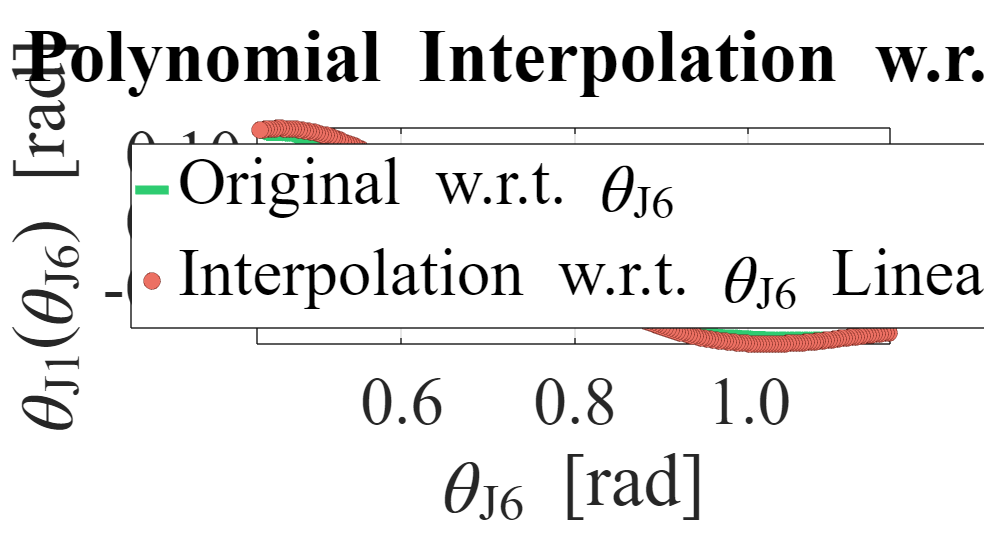

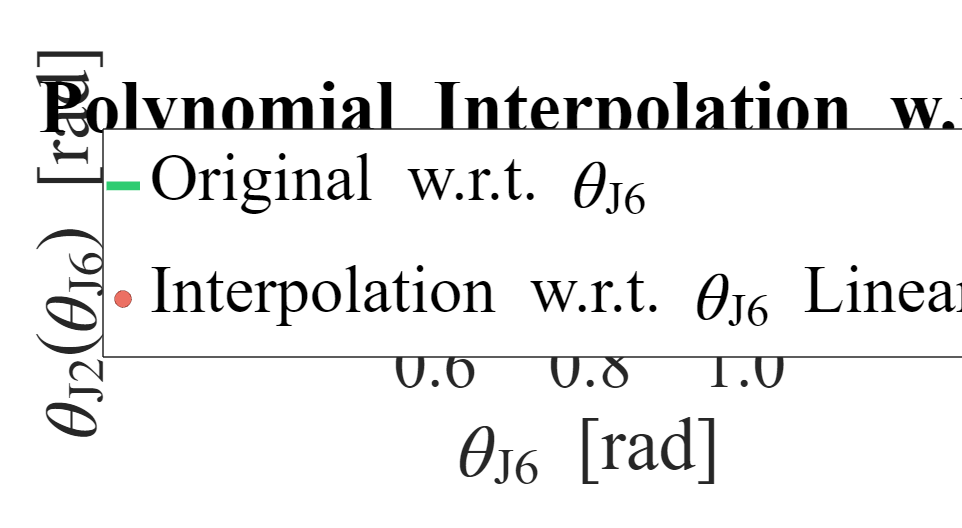

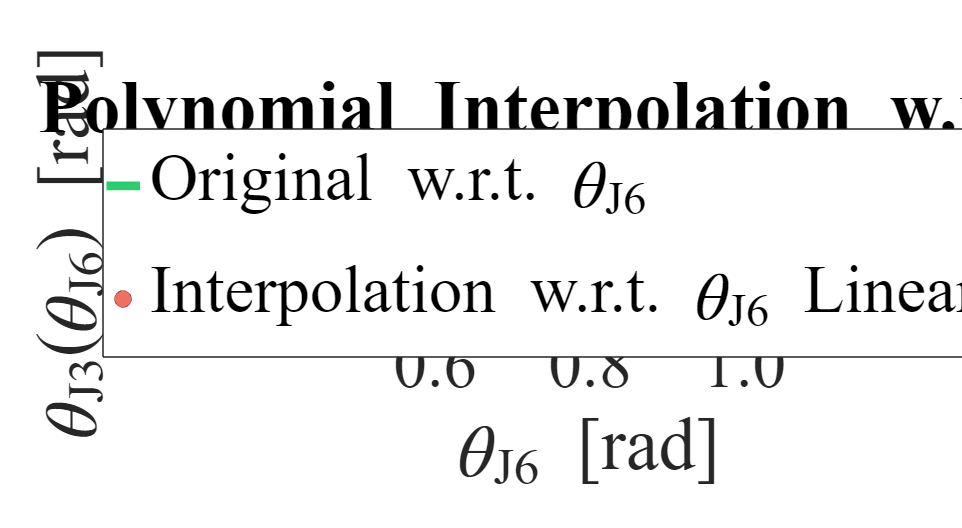

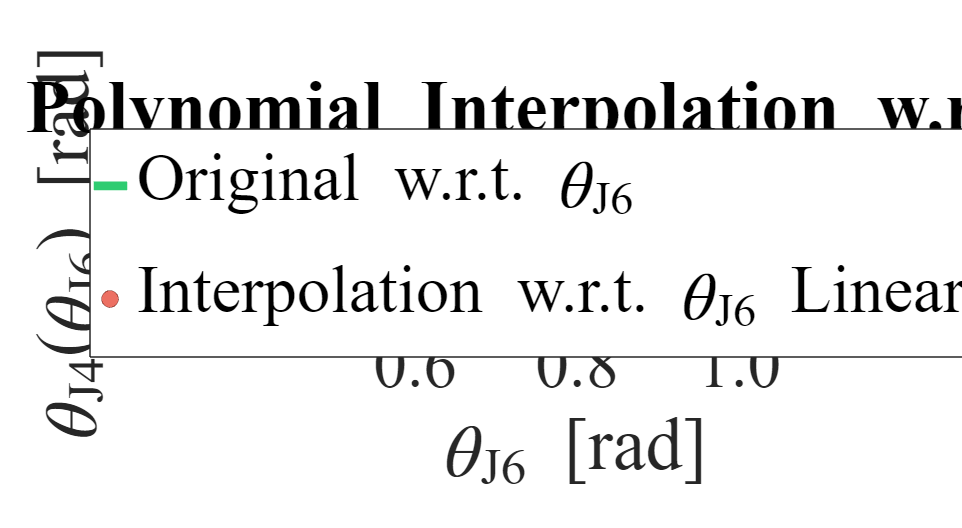

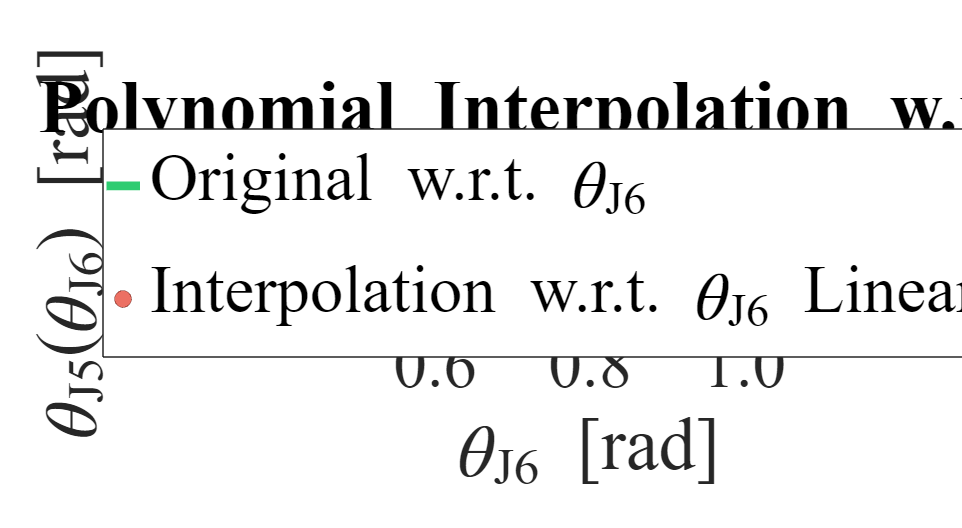

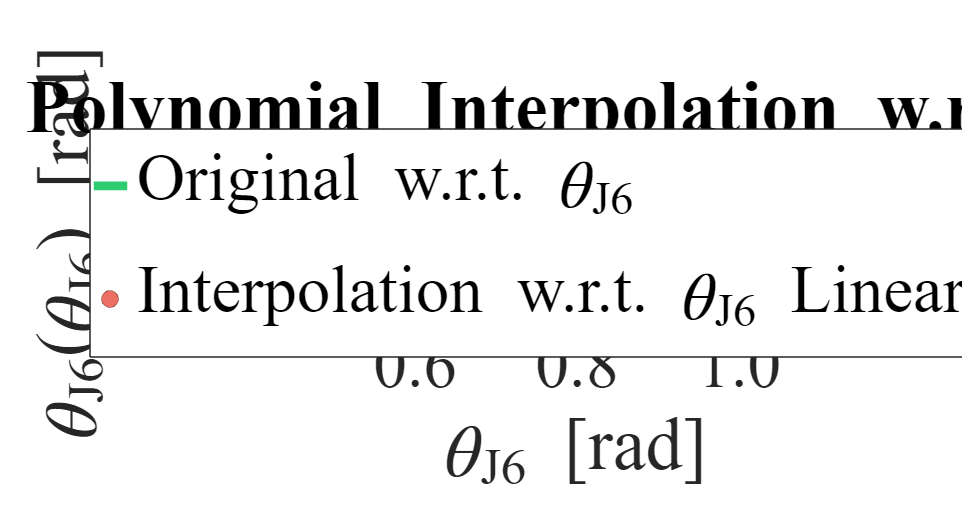

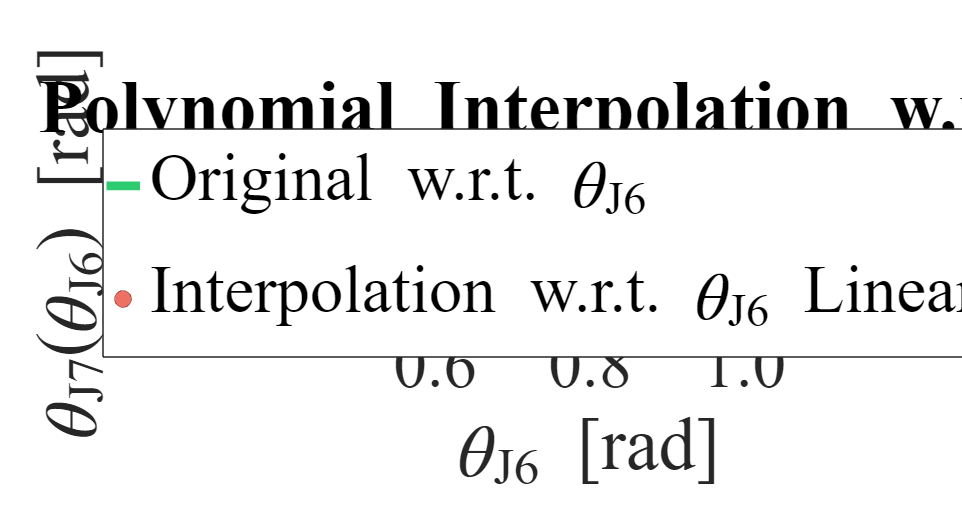

% Plot original and fitted trajectories for go
for i = 1:num_joints
    
    figure;

    % Modifica le dimensioni della figura per renderla più larga che alta
    set(gcf, 'Units', 'centimeters', 'Position', [0, 0, 80, 30]); % [left, bottom, width, height]
    
    % Imposta la dimensione di esportazione per fare in modo che il salvataggio
    % avvenga con la dimensione desiderata
    set(gcf, 'PaperUnits', 'centimeters');
    set(gcf, 'PaperPosition', [0, 0, width, height]);

    plot(go_angles(:,6), go_angles(:, i), '-', 'DisplayName', 'Original w.r.t. \theta_{J6}', 'Color', PS.LGreen2, 'LineWidth', 8);
    grid on;
    hold on;
    plot(go_fitted_angles(:,6), go_fitted_angles(:, i), 'LineStyle', 'none', 'Marker', 'o', 'MarkerSize', 15, 'MarkerEdgeColor', PS.Red5, 'MarkerFaceColor', PS.Red1, 'DisplayName', 'Interpolation w.r.t. \theta_{J6} Linear');
    title(['J', num2str(i), ' - 5^{th} degree Polynomial Interpolation w.r.t. \theta_{J6} - H. Abd. 60°'], 'FontName', font_name, 'FontSize', font_size);

    xlabel('\theta_{J6} [rad]',  'FontName', font_name, 'FontSize', font_size);
    ylabel(['\theta_{J', num2str(i), '}(\theta_{J6}) [rad]'], 'FontName', font_name, 'FontSize', font_size); % Specific ylabel for each joint
    xlim([minPosJ6 maxPosJ6]);
    legend('FontName', font_name, 'FontSize', font_size, 'Location', 'best');
    
    % Set the font properties for axes
    ax = gca; % Get current axis
    ax.FontName = font_name; % Set font name
    ax.FontSize = font_size; % Set font size
    
    ax.XTickLabel = num2str(get(gca, 'XTick')', '%.1f'); % Set Y axis ticks with 1 decimal place
    ax.YTickLabel = num2str(get(gca, 'YTick')', '%.2f'); % Set Y axis ticks with 1 decimal place


    % Salva il grafico come file SVG con dimensioni specifiche
    filename = ['J', num2str(i), '_5thInterp60.svg'];
    print(gcf, filename, '-dsvg');
end

**Return trajectories in function of J6**

- The Poly5 coeff are the same for both Go and Return since now all the joints are computed as function of the J6, hence they are time-independent.

- This means that we need just one Poly5 for each joint!

- In FloatEVO sw this coeff are written in the converse order wrt matlab (polyfit) in order of incresing power.

**Poly5 coeff for each joint**

go_fit_results

go_fit_results = 7×1 cell array
    {[ -0.0299 0.0930 0.3082 -1.4229 1.3840 -0.1593]}
    {[-0.0472 0.4212 -1.4431 2.3530 -1.8138 -0.9971]}
    {[ 0.0190 -0.3047 1.5035 -3.0368 2.3311 -0.3614]}
    {[  0.2248 -1.8298 5.4610 -7.2811 4.4098 1.0366]}
    {[-0.1164 0.8872 -2.4583 3.0376 -1.7804 -0.8416]}
    {[                               -0.4295 2.7499]}
    {[ 0.1168 -1.0463 3.5931 -5.8112 4.2557 -1.3455]}


**Gaussian Resistive Torque**

% % Gaussian parameters
% desired_max_torque = 7.5; % Nm 
% sigma = 0.5; % rad 
% q6_range = [minPosJ6, maxPosJ6]; % rad
% mean_shift = (minPosJ6 + maxPosJ6) / 2; % rad
% 
% % J6 positions in the given interval
% q6_values = linspace(minPosJ6, maxPosJ6, 1000);
% 
% % Needed amplitue to compute the max desired torque as the peak
% % peak value for a Gaussian centred in mean_shift and with st dev sigma
% max_pdf_value = (1/(sigma * sqrt(2 * pi))) * exp(-0.5 * ((mean_shift - mean_shift) / sigma)^2)
% % Scale factor to be multiplied to the gaussian in order to obtain a peak
% % exactly where desired (in the standardized distribution it is 1)
% torqueAmplitude = desired_max_torque / max_pdf_value

max_pdf_value = 0.7979

% % Resistive Gaussian Torque Profile
% resTorque = torqueAmplitude * (1/(sigma * sqrt(2 * pi))) * exp(-0.5 * ((q6_values - mean_shift) / sigma).^2);
% 

torqueAmplitude = 9.3999

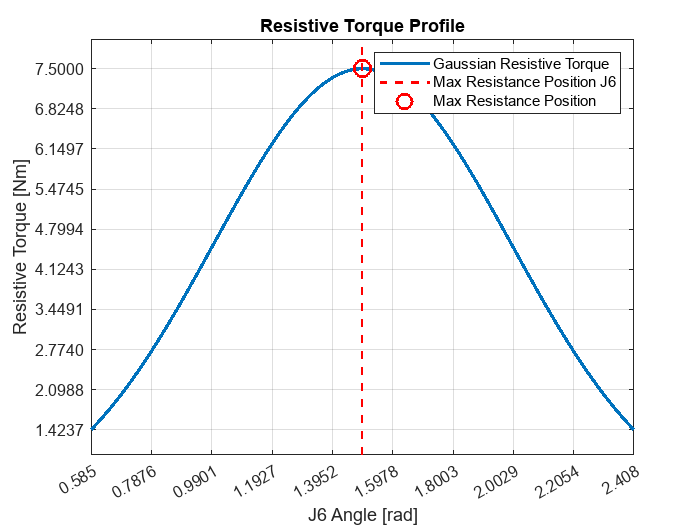

% % Find the position and the value of the max Torque
% [max_torque, max_index] = max(resTorque);
% max_q6 = q6_values(max_index);
% 
% % Plot Gaussian profile
% figure;
% plot(q6_values, resTorque, 'LineWidth', 2);
% hold on;
% title('Resistive Torque Profile');
% xlim([minPosJ6, maxPosJ6]);
% xlabel('J6 Angle [rad]');
% ylabel('Resistive Torque [Nm]');
% 
% % Plot vertical line corresponding to the max resistance pos
% y_limits = ylim;
% plot([max_q6, max_q6], y_limits, 'r--', 'LineWidth', 1.5); % Linea verticale
% 
% % Highlight the max resTorque 
% plot(max_q6, max_torque, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
% grid on;
% 
% % Adjust the grid in smaller interval
% xticks(linspace(min(q6_values), max(q6_values), 10)); 
% yticks(linspace(min(resTorque), max(resTorque), 10));
% legend('Gaussian Resistive Torque', 'Max Resistance Position J6', 'Max Resistance Position');